# Financial Engineering Project: 

# SPX Options Calibration - Affine Jump-diffusion Model

Author: Dantong Liu 刘丹彤

Email: dantongliu1999@outlook.com

LinkedIn: [http://linkedin.com/in/dantong-liu-273271311](http://linkedin.com/in/dantong-liu-273271311)

This project is based on the Affine Jump-diffusion Model (Bakshi, Cao & Chen(1997) and Bates(2006)) which is derived from Heston Model (Heston(1993)) and adding jumps in price process(SVJY model).


$$dX_t =\left(r-\bar{q} -\bar{\lambda} \mu_j -\frac{1}{2}V_t \right)\;\textrm{dt}+\sqrt{V_t }\;dW_t^s +J_t \;dP_t$$



$$dV_t =\kappa_{\upsilon } \left(\bar{\upsilon} -V_t \right)\;\textrm{dt}+\sigma_{\upsilon } \;dW_t^v \;$$


To find out more theoretical details, please see **Section 3.**

## **Summary:**

- **Section 1**: Removed options with negative bid prices, bid-ask spreads less than $5, missing prices, deep out-of-the-money, and deep in-the-money options.

- **Section 2**: Estimated the SPX index dividend yield and spot rate (risk-free rate) using put-call parity. Calculated implied volatility from SPX option market prices.

- **Section 3**: Explained the stochastic differential equation for the Affine Jump Diffusion model.

- **Section 4**: Prepared the two-part characteristic function: one for the Heston process and one for the pure jump process.

- **Section 5**: Presented the Call option pricing formula (Lewis' approach using inverse Fourier transform) and the objective function for parameter calibration (Average Relative Pricing Error, ARPE).

- **Section 6**: Conducted two-step calibration based on the two-part characteristic function. First, calibrated the pure jump process parameters by assuming the volatility of the price process was the minimum implied volatility of the most out-of-the-money option using the Interior-point algorithm (local optimization). Second, calibrated the Heston process parameters using Sequential Quadratic Programming (SQP), Interior-point, and Particle Swarm Optimization (PSO) algorithms (global optimization). Achieved an ARPE of 1.16, consistent with Kokholm (2016). Calibrating the Heston process parameters was particularly challenging.

- **Section 7**: Calculated SPX option model prices using the calibrated parameters and compared implied volatility surfaces between model prices and market prices for all strike prices and maturities.

- **Section 8**: Used Monte Carlo simulation to illustrate the SPX index path and its stochastic variance path.

- **Functions.**

## **Reference: **

- *Bates, D. S. (2006). Maximum likelihood estimation of latent affine processes. The Review of Financial Studies, 19(3), 909-965.*

- *Bakshi, G., Cao, C., & Chen, Z. (1997). Empirical performance of alternative option pricing models. The Journal of finance, 52(5), 2003-2049.*

- *Duffie, D., Pan, J., & Singleton, K. (2000). Transform analysis and asset pricing for affine jump‐diffusions. Econometrica, 68(6), 1343-1376. *

- *Heston, S. L. (1993). A closed-form solution for options with stochastic volatility with applications to bond and currency options. The review of financial studies, 6(2), 327-343.*

- *Lewis, A. (2001) A Simple Option Formula for General Jump-Di7usion and other  Exponential Lévy Processes, Envision Financial Systems and OptionCity.net,  California.*

- *Kokholm, T. (2016). Pricing and hedging of derivatives in contagious markets. Journal of Banking & Finance, 66, 19-34.*

- *Schoutens, W., Simons, E., & Tistaert, J. (2003). A perfect calibration! Now what?. The best of Wilmott, 281.*

clear;  clc;

% load data
data = readtable('SPX.csv');

% variables
market_price = data.market_price;   % market price = 0.5 * (best_bid + best offer)
maturity = data.maturity;           % maturity =exdate - today(net working days),  
T = data.tao;                       % tao = maturity/252
strike = data.strike;               % K

S0 = 3094.04;   % underlying SPX index closing price

## **1. Clean Data (remove data who unsatisfy below restrictions)**

- bid price > 0

- moneyness 0.8 < K/S0 < 1.2

- bid-ask spread < $5

- no missing put and call prices

% clean data
BidAskSpread = data.('best_bid') - data.('best_offer');

condition1 = data.('best_bid') > 0;         % Bid price > 0
condition2 = BidAskSpread < 5;              % Bid-ask spread < $5
condition3 = ~isnan(market_price);          % No missing prices

% conditions
combinedConditions = condition1 & condition2 & condition3;
filteredData = data(combinedConditions, :);

% split Call_data & Put_data
Call_data = filteredData(strcmp(filteredData.cp_flag, 'C'), ...
    {'market_price', 'strike', 'tao', 'maturity', 'cp_flag'});
Put_data = filteredData(strcmp(filteredData.cp_flag, 'P'), ...
    {'market_price', 'strike', 'tao', 'maturity', 'cp_flag'});

% 4 shortest maturities
short_maturity = [28, 48, 73, 93];  

OTM4_Call = [];
OTM4_Put = [];

% 8 most out-of-money options
for i = 1:length(short_maturity)
    current_maturity = short_maturity(i);
    current_Call = Call_data(Call_data.maturity == current_maturity, :);
    current_Call.OTM = current_Call.strike - S0;
    
    if height(current_Call) >= 4
        [~, call_idx] = maxk(current_Call.OTM, 4);
    else
        call_idx = 1:height(current_Call);
    end
    OTM4_Call = [OTM4_Call; current_Call(call_idx, :)];

    current_Put = Put_data(Put_data.maturity == current_maturity, :);
    current_Put.OTM = current_Put.strike - S0;
    
    if height(current_Put) >= 4
        [~, Put_idx] = maxk(current_Put.OTM, 4);
    else
        Put_idx = 1:height(current_Put);
    end
    OTM4_Put = [OTM4_Put; current_Put(Put_idx, :)];
end

OTM4_Options = [OTM4_Call; OTM4_Put];
OTM4_Options = sortrows(OTM4_Options, {'maturity', 'strike'});
% save
writetable(OTM4_Options, 'OTM4_options.csv');

% merge
Call_data.Properties.VariableNames{'market_price'} = 'Call_market';
Call_data = removevars(Call_data, {'cp_flag'});
Put_data.Properties.VariableNames{'market_price'} = 'Put_market';
Put_data = removevars(Put_data, {'cp_flag'});
new_data = outerjoin(Call_data, Put_data, 'Keys', {'tao', ...
    'maturity', 'strike'}, 'MergeKeys', true);

new_data.moneyness = new_data.strike ./ S0;
% moneyness 0.8 < K/S0 < 1.2
condition4 = new_data.moneyness > 0.6 & new_data.moneyness < 1.4;    
new_data = new_data(condition4, :);

% drop NAN
new_data = rmmissing(new_data);

% save csv
writetable(new_data, 'new_data.csv');

clear;  clc;

% load data
data = readtable('new_data.csv');
disp(data(1:5, :));

    Call_market    strike      tao      maturity    Put_market    moneyness
    ___________    ______    _______    ________    __________    _________

      1041.2        2050     0.11111       28         0.075        0.66256 
      1016.3        2075     0.11111       28         0.075        0.67064 
       981.4        2110     0.11111       28         0.075        0.68196 
       971.4        2120     0.11111       28         0.075        0.68519 
      966.45        2125     0.11111       28           0.1         0.6868 



## **2. Dividend Yield **$q$** and Spot Rates **$r_{\tau_i }$ 

Minimize the objective function: 


$$\sum_{i=1}^m \sum_{j=1}^{2n} {\left(P\left(\tau_i ,K_j^i \right)-P^{\textrm{PC}} \left(C\left(\tau_i ,K_j^i \right),q,r_{\tau_i } \right)\right)}^2$$


where 


$$P^{\textrm{PC}} \left(C\left(\tau_i ,K_j^i \right),q,r_{\tau_i } \right)=C\left(\tau_i ,K_j^i \right)+K_j^i e^{-r_{\tau_i } \tau_i } -S_0 \;e^{-q\tau_i }$$


$n$ denote the number of option pairs on each side of ATM (e.g. n = 5), and $\textrm{PC}$ denote put-call parity.

n = 5;          % ATM option pairs
S0 = 3094.04;   % underlying SPX index closing price

% each maturity
unique_maturities = unique(data.tao);      % noted annulized tao
selected_data = table();

for i = 1:length(unique_maturities)
    T = unique_maturities(i);
    current_data = data(data.tao == T, :);
    
    % collect ATM options
    calls = current_data(current_data.strike > S0, :);
    if ~isempty(calls)
        calls_sorted = sortrows(calls, 'strike', 'ascend');
        selected_data = [selected_data; calls_sorted(1:min(n, height(calls_sorted)), :)];
    end
    
    puts = current_data(current_data.strike < S0, :);
    if ~isempty(puts)
        puts_sorted = sortrows(puts, 'strike', 'descend');
        selected_data = [selected_data; puts_sorted(1:min(n, height(puts_sorted)), :)];
    end
end

% for each maturity
unique_selected_maturities = unique(selected_data.tao);
M = length(unique_selected_maturities); 

% initial guess
% [q, r1, r2, ..., rM]
initial_q = 0.02;               % dividend yield q 
initial_r = 0.01 * ones(M, 1);  % spot rate r
initial_guess = [initial_q; initial_r];

% optimzation - no contraints
options = optimoptions('fminunc', 'Display', 'iter', 'Algorithm', ...
    'quasi-newton', 'MaxFunctionEvaluations', 1e4, 'MaxIterations', 1e4);
[estimated_params, fval] = fminunc(@(params) objective_function_q_r(params, ...
    selected_data, unique_selected_maturities, S0), initial_guess, options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0          14           111547                      2.24e+07
     1          70          2632.88    3.58243e-10       1.23e+06  
     2          84          1980.64              1       9.88e+05  
     3          98          583.813              1       3.67e+05  
     4         112          521.841              1        3.2e+05  
     5         126          307.802              1       1.03e+05  
     6         140          295.506              1       9.26e+04  
     7         154          205.859              1        1.1e+05  
     8         168          169.355              1       8.11e+04  
     9         182          150.724              1       7.05e+04  
    10         196          143.405              1       6.41e+04  
    11         210          130.279              1       7.04e+04  
    12         224          112.671              

% results
q_estimated = estimated_params(1);              
r_estimated = estimated_params(2:end);          

r_table = table(unique_selected_maturities, r_estimated, 'VariableNames', ...
    {'tao', 'Spot_Rate'});
writetable(r_table, 'r_table.csv');

% print
fprintf('Estimated dividend yield (q): %.4f\n', q_estimated);

Estimated dividend yield (q): 0.0182


disp('Estimated spot rate (r) for each maturity:');

Estimated spot rate (r) for each maturity:


disp(r_table);

      tao      Spot_Rate
    _______    _________

    0.11111    0.015879 
    0.19048    0.021671 
    0.28968    0.020289 
    0.36905    0.019598 
    0.44841    0.020045 
    0.62698    0.018984 
    0.88492    0.018483 
    0.96429    0.018821 
     1.0635    0.018387 
     1.1429    0.018069 
     1.6587    0.017832 
     2.1746    0.017673 



% merge
mergeddata = join(data, r_table, 'Keys', 'tao'); 
writetable(mergeddata, 'merged_data.csv');

data = readtable('OTM4_options.csv');
data = join(data, r_table, 'Keys', 'tao'); 
writetable(data, 'OTM4_options.csv');

% calculate market price impled volatility
clear;  clc;
mergeddata = readtable('merged_data.csv');

C_market_price = mergeddata.Call_market;
P_market_price = mergeddata.Put_market;
K = mergeddata.strike;
T = mergeddata.tao;
r = mergeddata.Spot_Rate;
q_estimated = 0.0182;
S0 = 3094.04;   

N = length(K);
IV_C_MK = zeros(N, 1);
IV_P_MK = zeros(N, 1);

for i = 1:N
    K_i = K(i);
    T_i = T(i);
    r_i = r(i) - q_estimated;
    C_market_price_i = C_market_price(i);
    IV_C_MK(i) = bsm_implied_vol_call(C_market_price_i, S0, K_i, r_i, T_i, q_estimated);
    P_market_price_i = P_market_price(i);
    IV_P_MK(i) = bsm_implied_vol_put(P_market_price_i, S0, K_i, r_i, T_i, q_estimated);
end
mergeddata.IV_C_MK = IV_C_MK;
mergeddata.IV_P_MK = IV_P_MK;
writetable(mergeddata, 'merged_data.csv');

clear;  clc;
data = readtable('OTM4_options.csv');

market_price = data.market_price;
K = data.strike;
T = data.tao;
r = data.Spot_Rate;
cp_flag = data.cp_flag;
q_estimated = 0.0182;
S0 = 3094.04;   

N = length(K);
IV_MK = zeros(N, 1);

for i = 1:N
    K_i = K(i);
    T_i = T(i);
    r_i = r(i) - q_estimated;
    cp_flag_i = cp_flag{i};
    market_price_i = market_price(i);
    if cp_flag_i == 'C'
        IV_MK(i) = bsm_implied_vol_call(market_price_i, S0, K_i, r_i, T_i, q_estimated);
    else 
        IV_MK(i) = bsm_implied_vol_put(market_price_i, S0, K_i, r_i, T_i, q_estimated);
    end
end

data.IV_MK = IV_MK;
writetable(data, 'OTM4_options.csv');


## **3. Affine Jump-diffusion Model: Stochastic Differential Equation (SDE)**

Stochastic volatility with independent jumps in log price process (Bakshi, Cao & Chen(1997)). In more generalized circumstance, jumps also may occur in Variance process(like the SVJJ model in Duffie, Pan & Singleton(2000)), even affected by other securities (like the Contagion model in Kokholm(2016)). But today, I only consider jumps in log price process.


$$dX_t =\left(r-\bar{q} -\bar{\lambda} \mu_j -\frac{1}{2}V_t \right)\;\textrm{dt}+\sqrt{V_t }\;dW_t^s +J_t \;dP_t$$



$$dV_t =\kappa_{\upsilon } \left(\bar{\upsilon} -V_t \right)\;\textrm{dt}+\sigma_{\upsilon } \;dW_t^v \;$$


Notations

- $X_t \;\;=\;\ln {\;S}_t$ underlying SPX index at time t

- $V_t$ Variance of SPX index at time t (stochastic volatility)

- $r$ spot rate 

- $\bar{q}$ constant dividend yield

- $\kappa_{\upsilon }$ speed of mean reversion

- $\bar{\upsilon}$  long-term average level of variance

- $\sigma_{\upsilon }$ volatility of variance

- $W_t^s$ and $W_t^v$ are correlated Standard Brownian Motion with coefficient $\bar{\rho}$

- $\textrm{dt}$ an infinitesimal increment of time

- $J_t$ normally distributed jump size with mean $\mu_j$ and variance $\sigma_j^2$

- $dP_t$ Poisson process with intensity $\bar{\lambda}$

## 4. Characteristic Function: Exponential-affine Form (calibration method from Kokholm(2016))

Split the characteristic function into 2 parts: $\Psi \left(u,\tau \right)=\psi_1 \left(u,\tau \right)*\psi_2 \left(u,\tau \right)\;$ At time 0, $\tau =T-t=T$.

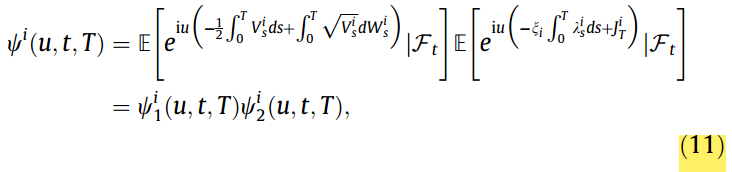

### **4.1) stochastic volatility process (Heston process)**

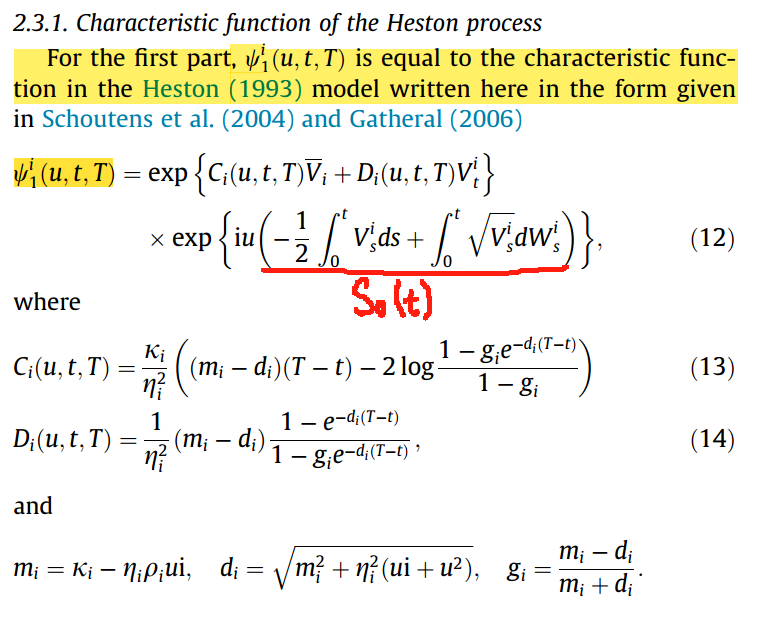

### **4.2) pure jump process**

First, calibrate pure jump process parameters by below characteristic function, then calibrate stochastic volatility process parameters by former Heston process.

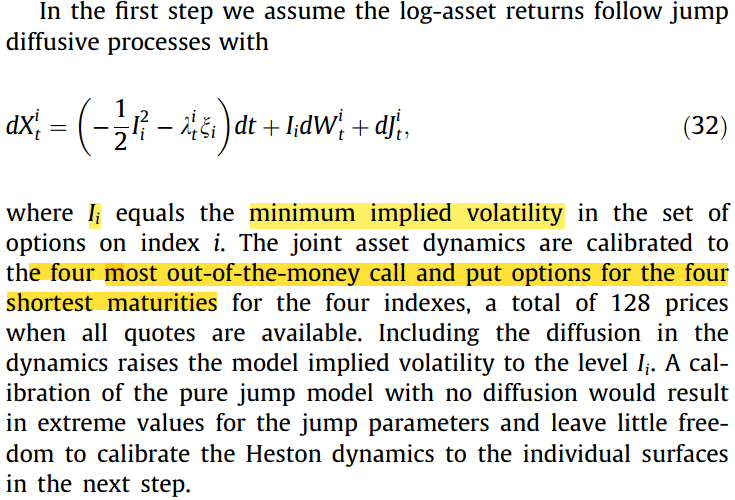


$$\psi_2 \left(u,\tau \right)=\exp \left(\bar{\lambda} \tau \left(e^{\textrm{iu}\mu_j -\frac{1}{2}u^2 \sigma_j^2 } -1\right)+\textrm{iu}\;\ln S_0 -\frac{1}{2}I^2 u^2 \tau +\textrm{iu}\tau \left(-\frac{1}{2}I^2 -\bar{\lambda} \left(e^{\mu_j +\frac{1}{2}\sigma_j^2 } -1\right)\right)\right)$$


## 5. Option Pricing Formula: Lewis' Approach (Inverse Fourier Transform) (method from Kokholm(2016))


$$C\left(K,S_0 ,\;\tau \right)=S_0 -\;\frac{\sqrt{S_0 K}e^{-\frac{1}{2}\left(r-\bar{q} \right)\tau } }{\pi }\int_0^{\infty } \frac{\Re \left(e^{-\textrm{iu}\;\left(\log \left(\frac{S_0 }{K}\right)+\left(r-\bar{q} \right)\tau \right)} \;\Psi \left(u-\frac{i}{2}\right)\right)}{\left(u^2 +\frac{1}{4}\right)}\;\textrm{du}$$


The pure jump parameters calibration was done by minimizing the sum-squared pricing error (SSE), defined as the sum of the squared differences between the observed and the modeled option prices across all strikes and maturities. 


$$\textrm{SSE}=\sum \left({\left({\textrm{IV}}^{\textrm{market}} -{\textrm{IV}}^{\textrm{model}} \right)}^2 \right)$$


The Heston process parameters calibration was done by minimizing the Average Relative Pricing Error(ARPE), defined as below:

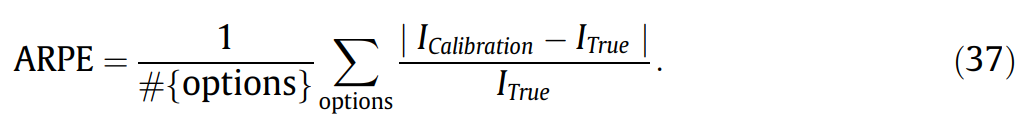 

## **6. Calibration**

### **6.1) First step: calibrate the pure jump parameters by 4.2) characteristic function and 5) Lewis' Fourier Transform Approach. **

- $\bar{\lambda} =1\ldotp 1004$         constant jump intensity (Poisson process)

- $\mu_j =-0\ldotp 0612$     mean of jump size (normally distributed)

- $\sigma_j =0\ldotp 0573$        volatility of jump size (normally distributed)

clear;  clc;

% load data
rawdata = readtable('OTM4_options.csv');
C_data = rawdata(strcmp(rawdata.cp_flag, 'C'), :);
C_market_price = C_data.market_price;
K = C_data.strike;
T = C_data.tao;
r = C_data.Spot_Rate;
IV_C_MK = C_data.IV_MK;
q_estimated = 0.0182;
S0 = 3094.04;   

% minimum implied volatility
IV_market = min(IV_C_MK)

IV_market = 0.1036

% [lambda_bar, sigma_j, mu_j]
initial_params = [2, 0.1, -0.3];

% boundary
lb = [0.001, 0.0001, -1];  
ub = [10, 1, 0]; 

% calibrate
options = optimset('Display', 'iter');
calibrated_params = fmincon(@(params) objectiveFunction_purejump(params, ...
    K, S0, T, r, q_estimated, IV_market, IV_C_MK), ...
    initial_params, [], [], [], [], lb, ub, [], options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    2.236420e+00    0.000e+00    2.618e+00
    1       8    3.796254e-02    0.000e+00    9.841e+00    8.979e-01
    2      12    3.992845e-02    0.000e+00    5.726e-01    7.032e-02
    3      17    1.595036e-01    0.000e+00    1.413e+00    1.396e-01
    4      21    9.754898e-02    0.000e+00    2.491e-01    2.460e-01

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the 

disp('Calibrated Pure Jump Parameters:');

Calibrated Pure Jump Parameters:


% [lambda_bar, sigma_j, mu_j]   
disp(calibrated_params);

    1.1004    0.0573   -0.0612



### **6.2) Second step: calibrate the Heston process parameters by combining 4.1) with 4.2) characteristic functions and 5) Lewis' Fourier Transform Approach. **

clear;  clc;
calibrated_params = [1.1004, 0.0573, -0.0612];
% load data
data = readtable('merged_data.csv');
disp(data(1:5, :));

    Call_market    strike      tao      maturity    Put_market    moneyness    Spot_Rate    IV_C_MK    IV_P_MK
    ___________    ______    _______    ________    __________    _________    _________    _______    _______

      1041.2        2050     0.11111       28         0.075        0.66256     0.015879     0.60569    0.39083
      1016.3        2075     0.11111       28         0.075        0.67064     0.015879     0.59121    0.37999
       981.4        2110     0.11111       28         0.075        0.68196     0.015879     0.57176      0.365
       971.4        2120     0.11111       28         0.075        0.68519     0.015879      0.5656    0.36076
      966.45        2125     0.11111       28           0.1         0.6868     0.015879      0.5636    0.36725



Call_market = data.Call_market;
IV_C_MK = data.IV_C_MK;
K = data.strike;
T = data.tao;
r = data.Spot_Rate;
q_estimated = 0.0182;
S0 = 3094.04;   % underlying SPX index closing price

- Because of the highly dimensional complex structure of characteristic function, parameters of Affine Jump-diffusion model are very uneasy to calibrate. First, I tried to use SQP Algorithm (local optimization) to find the parameters in a relatively large range around empirical initial guess. You can see the calibrated result is very easy to fall into the wrong local optimal solution.

% parameters = [kappa_v, sigma_v, rho_bar, v_bar, v0]   
initial_heston_params = [1, 1.5, -0.5, 0.02, 0.02];

% boundary
lb = [0.1, 0.5, -0.99, 0.01, 0.01];
ub = [3,    2,     0,   0.1,  0.1]; 

% Sequential quadratic programming (SQP)
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp', ...
                       'MaxFunctionEvaluations', 1e4, 'MaxIterations', 1e4);

[optimal_params, fval] = fmincon(@(params) objective_function_hestonjump(params, ...
    IV_C_MK, K, T, S0, r, q_estimated, calibrated_params), ...
    initial_heston_params, [], [], [], [], lb, ub, [], options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    1.160528e+00     0.000e+00     1.000e+00     0.000e+00     3.789e-02  
    1          12    1.159391e+00     0.000e+00     1.000e+00     3.800e-02     3.944e-02  
    2          18    1.155999e+00     0.000e+00     1.000e+00     1.326e-01     1.199e-02  
    3          24    1.155987e+00     0.000e+00     1.000e+00     4.570e-03     1.093e-02  
    4          30    1.155954e+00     0.000e+00     1.000e+00     1.151e-02     1.185e-02  
    5          36    1.155837e+00     0.000e+00     1.000e+00     4.412e-02     2.494e-02  
    6          42    1.155765e+00     0.000e+00     1.000e+00     2.715e-02     3.206e-03  
    7          49    1.155764e+00     0.000e+00     7.000e-01     1.697e-03     2.322e-03  
    8          56    1.155763e+00     0.000e+00     7.000e-01     3.069e-04     3.

Calibrated Heston+Jump parameters:


% [kappa_v, sigma_v, rho_bar, v_bar, v0]   
disp(optimal_params);

    0.9977    1.5017   -0.4899    0.3000    0.2000



- Second, I tried a more narrow range and change to Interior-point Algorithm, the calibrated v_bar and v0 are also very close to their upper boundaries. ARPE is around 1.161 that is close to the ARPE value in Kokholm(2016).

% local optimization: interior-point

% parameters = [kappa_v, sigma_v, rho_bar, v_bar, v0]   
initial_heston_params = [1, 1.5, -0.5, 0.02, 0.02];

% boundary
lb = [0.5, 0.5, -0.99, 0.01, 0.01];
ub = [5,    2,     0,  0.03, 0.03];

options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'interior-point', ...
                       'MaxFunctionEvaluations', 1e4, 'MaxIterations', 1e4);

[optimal_params, fval] = fmincon(@(params) objective_function_hestonjump(params, ...
    IV_C_MK, K, T, S0, r, q_estimated, calibrated_params), ...
    initial_heston_params, [], [], [], [], lb, ub, [], options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.161303e+00    0.000e+00    1.310e-02
    1      12    1.161294e+00    0.000e+00    3.257e-03    2.001e-03
    2      18    1.161295e+00    0.000e+00    8.582e-03    9.958e-03
    3      24    1.161248e+00    0.000e+00    9.237e-03    3.568e-02
    4      30    1.161228e+00    0.000e+00    9.047e-03    5.676e-02
    5      36    1.161156e+00    0.000e+00    5.890e-03    1.536e-01
    6      42    1.161291e+00    0.000e+00    7.506e-03    2.455e-01
    7      48    1.161318e+00    0.000e+00    1.107e-02    3.622e-01
    8      59    1.161277e+00    0.000e+00    1.628e-03    2.666e-01
    9      67    1.161190e+00    0.000e+00    5.812e-03    2.429e-02
   10      78    1.161177e+00    0.000e+00    5.502e-04    1.377e-03
   11      84    1.161123e+00    0.000e+00    5.278e-03    2.888e-02
   12      90    1.161022e+00    0.000e+00    6

Calibrated Heston+Jump parameters:


% [kappa_v, sigma_v, rho_bar, v_bar, v0]   
disp(optimal_params);

    1.9524    1.0113   -0.4483    0.0298    0.0299



- Third, I tried the Global Optimization Algorithm (Particle Swarm Optimization). Noted, the Global Optimization Algorithm spent much longer time to calculate, so I only set 20 MaxStallIterations and 30 SwarmSize but it still spent 4 hours to get the results.

% global optimization: Particle Swarm Optimization (PSO)

% parameters = [kappa_v, sigma_v, rho_bar, v_bar, v0]   
initial_heston_params = [1, 1.5, -0.5, 0.02, 0.02];

% boundary
lb = [0.5, 0.5, -0.9, 0.01, 0.01];
ub = [5,    2,     0, 0.03, 0.03];

options = optimoptions('particleswarm', 'Display', 'iter', ...
                       'MaxIterations', 1e4, 'MaxStallIterations', 20, ...
                       'SwarmSize', 30); 

nvars = length(initial_heston_params);  

[optimal_params, fval] = particleswarm(@(params) objective_function_hestonjump( ...
    params, IV_C_MK, K, T, S0, r, q_estimated, calibrated_params), nvars, lb, ub, options);


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              30           1.161           1.161        0
    1              60           1.161           1.161        0
    2              90           1.161           1.161        0
    3             120           1.161           1.161        0
    4             150           1.161           1.161        1
    5             180           1.161           1.161        0
    6             210           1.161           1.161        0
    7             240            1.16           1.161        0
    8             270            1.16           1.161        1
    9             300            1.16           1.161        2
   10             330            1.16           1.161        3
   11             360            1.16           1.161        4
   12             390            1.16           1.161        5
   13             420            1.16           

Calibrated Pure Heston parameters:


% [kappa_v, sigma_v, rho_bar, v_bar, v0]   
disp(optimal_params);

    0.5000    2.0000   -0.6916    0.0286    0.0300



## 7. Implied Volatility Surface

Even though the calibrated parameters are not completely correct, I still applied them to illustrate the implied volatility surface. The implied volatilities derived from model price is much higher than implied volatilities from market price, and they almost equals zero if the option strike prices are higher than spot price S0 (out-of-money call options). These strange implied volatilities may be explained by the wrong calibrated parameters.

numRows = height(data); % 行数
Call_model = zeros(numRows, 1); % 预分配为列向量
IV_C_MD = zeros(numRows, 1);

% the local optimization results (by Interior-point Algorithm) 
optimal_params = [1.9524, 1.0113, -0.4483, 0.0298, 0.0299]; 
calibrated_params = [1.1004, 0.0573, -0.0612];

% calculate Affine Jump-diffusion model price and implied volatility
for i = 1:numRows
    K_i = K(i);
    T_i = T(i);
    r_i = r(i);
    Call_model(i) = hestonjump_Lewis_call(S0, data.strike(i), data.tao(i), ...
        data.Spot_Rate(i), q_estimated, optimal_params(1), optimal_params(2), ...
        optimal_params(3), optimal_params(4), optimal_params(5), ...
        calibrated_params(1), calibrated_params(2), calibrated_params(3));
    IV_C_MD(i) = bsm_implied_vol_call(Call_model(i), S0, K_i, r_i, T_i, q_estimated);
end

data.CallModel = Call_model;
data.IV_C_MD = IV_C_MD;
writetable(data, 'IV_data.csv');

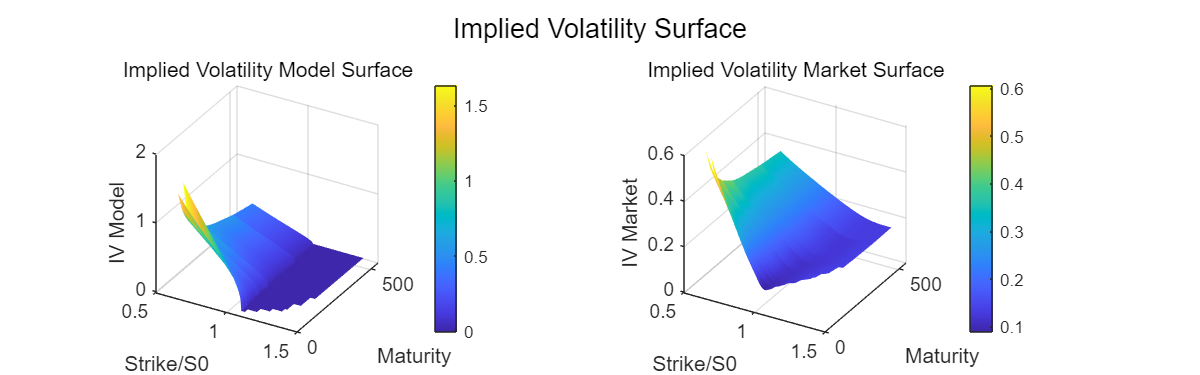

ivdata = readtable('IV_data.csv');

S0 = 3094.04; 

x = ivdata.strike / S0;  
y = ivdata.maturity;    
plotIV_C_MD = ivdata.IV_C_MD;
plotIV_C_MK = ivdata.IV_C_MK;

[X, Y] = meshgrid(unique(x), unique(y)); 

IV_model_interp = griddata(x, y, plotIV_C_MD, X, Y, 'cubic');
IV_market_interp = griddata(x, y, plotIV_C_MK, X, Y, 'cubic');

figure('Position', [100, 100, 800, 250]); 

% IV_model
subplot(1, 2, 1); 
surf(X, Y, IV_model_interp, 'EdgeColor', 'none'); 
xlabel('Strike/S0');
ylabel('Maturity');
zlabel('IV Model');
title('Implied Volatility Model Surface');
colorbar; 
view(30, 30); 

% IV_market
subplot(1, 2, 2); 
surf(X, Y, IV_market_interp, 'EdgeColor', 'none');
xlabel('Strike/S0');
ylabel('Maturity');
zlabel('IV Market');
title('Implied Volatility Market Surface');
colorbar; 
view(30, 30); 

sgtitle('Implied Volatility Surface'); 

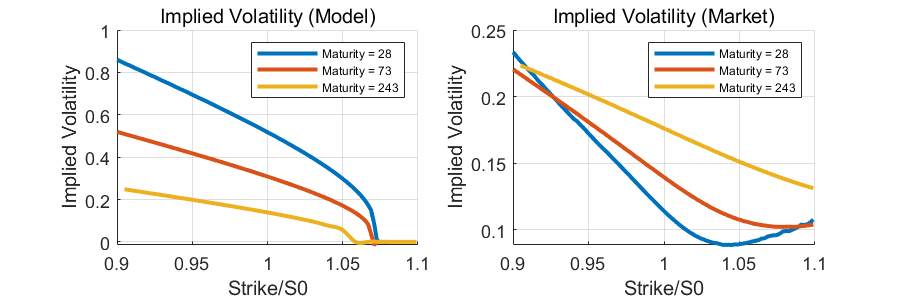

% implied volatility

x = ivdata.strike / S0; 
y_maturity = ivdata.maturity;  
plotIV_C_MD = ivdata.IV_C_MD;   
plotIV_C_MK = ivdata.IV_C_MK;   

% only maturity 1 month, 3 month, 12 month
unique_maturities = [28, 73, 243];

colors = lines(length(unique_maturities));  
figure('Position', [100, 100, 600, 200]);  

% IV_model
subplot(1, 2, 1);  
hold on;

for idx = 1:length(unique_maturities)
    current_maturity = unique_maturities(idx);
    
    x_current = x(y_maturity == current_maturity);
    iv_current = plotIV_C_MD(y_maturity == current_maturity);  
    
    valid_indices = (x_current > 0.9) & (x_current < 1.1);    % strike price around S0
    x_filtered = x_current(valid_indices);
    iv_filtered = iv_current(valid_indices);

    xq = linspace(min(x_filtered), max(x_filtered), 100);  
    ivq = interp1(x_filtered, iv_filtered, xq, 'spline');  

    plot(xq, ivq, 'Color', colors(idx, :), 'LineWidth', 2, 'DisplayName', ...
        sprintf('Maturity = %d', current_maturity));
end

xlabel('Strike/S0');
ylabel('Implied Volatility');
title('Implied Volatility (Model)');
legend('show');  
set(legend, 'FontSize', 6);
grid on;
hold off;

% IV_market
subplot(1, 2, 2); 
hold on;

for idx = 1:length(unique_maturities)
    current_maturity = unique_maturities(idx);

    x_current = x(y_maturity == current_maturity);
    iv_current = plotIV_C_MK(y_maturity == current_maturity);  

    valid_indices = (x_current > 0.9) & (x_current < 1.1);    % strike price around S0
    x_filtered = x_current(valid_indices);
    iv_filtered = iv_current(valid_indices);

    xq = linspace(min(x_filtered), max(x_filtered), 100); 
    ivq = interp1(x_filtered, iv_filtered, xq, 'spline');  

    plot(xq, ivq, 'Color', colors(idx, :), 'LineWidth', 2, 'DisplayName', ...
        sprintf('Maturity = %d', current_maturity));
end

xlabel('Strike/S0');
ylabel('Implied Volatility');
title('Implied Volatility (Market)');
legend('show'); 
set(legend, 'FontSize', 6);
grid on;
hold off;

## 8. Monte Carlo Simulation: Price and Variance paths

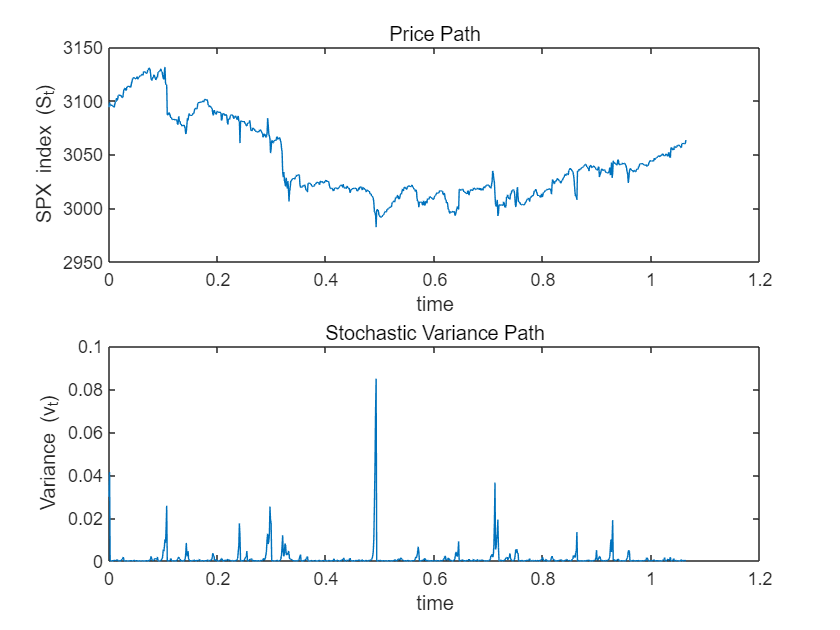

clear;  clc;

% the local optimization results (by Interior-point Algorithm) 
optimal_params = [1.9524, 1.0113, -0.4483, 0.0298, 0.0299]; 
calibrated_params = [1.1004, 0.0573, -0.0612];

S0 = 3094.04;    
q_estimated = 0.0182;
r = 0.0184;           % 268 days spot rate
T = 1.0635;           % 268 days maturity 
kappa_v = optimal_params(1);     
sigma_v = optimal_params(2);    
rho_bar = optimal_params(3);  
v_bar = optimal_params(4);    
v0 = optimal_params(5);     
lambda_bar = calibrated_params(1);  
sigma_j = calibrated_params(2);  
mu_j = calibrated_params(3);  
num_paths = 1; 
num_steps = 1000; 

% Monte Carlo Simulation
[S_paths, v_paths, time_vector] = simulate_heston_jump(S0, v0, r, q_estimated, ...
    T, kappa_v, v_bar, sigma_v, rho_bar, lambda_bar, mu_j, sigma_j, num_paths, num_steps);

figure;
subplot(2, 1, 1);
plot(time_vector, S_paths(1, :)');  % price
xlabel('time');
ylabel('SPX index (S_t)');
title('Price Path');

subplot(2, 1, 2);
plot(time_vector, v_paths(1, :)');  % variance
xlabel('time');
ylabel('Variance (v_t)');
title('Stochastic Variance Path');

function C = purejump_Lewis_call(S0, K, T, r, q_estimated, lambda, mu_j, sigma_j, IV_market)
    i = 1i;   % imaginary unit
    
    f = @(u) real(purejump_CF(u-0.5i, T, r, q_estimated, lambda, sigma_j, mu_j, ...
        IV_market) .* exp(i*u*(log(S0/K)+(r-q_estimated)*T))) ./ (u^2 + 0.25);
    integrand = integral(f, 0.001, 100, 'ArrayValued', true);
    
    % Lewis' Approach
    C = S0 * exp(-q_estimated * T) - sqrt(S0*K)*exp(-0.5*(r+q_estimated)*T) * ( ...
        (1/ pi) * integrand);
end

function C = hestonjump_Lewis_call(S0, K, T, r, q_estimated, kappa_v, sigma_v, rho_bar, ...
    v_bar, v0, lambda_bar, sigma_j, mu_j)
    i = 1i;   % imaginary unit

    f = @(u) real(heston_CF(u-0.5i, S0, T, r, q_estimated, kappa_v, sigma_v, rho_bar, ...
        v_bar, v0, lambda_bar, sigma_j, mu_j) .* exp(i*u*(log(S0/K)+(r-q_estimated)*T) ...
        ) ./ (u^2 + 0.25)); 
    integrand = integral(f, 0.001, 100, 'ArrayValued', true);
    
    % Lewis' Approach
    C = S0 * exp(-q_estimated * T) - sqrt(S0*K)*exp(-0.5*(r-q_estimated)*T) * ( ...
        (1/ pi) * integrand);
end

function phi = purejump_CF(u, T, r, q_estimated, lambda, sigma_j, mu_j, IV_market)
    jumpterm = exp(-lambda*mu_j*1i*u*T + ...
        lambda*T*((1+mu_j)^(1i*u) * exp(0.5*sigma_j^2*1i*u*(1i*u-1)) - 1));
    drift = 1i .* u .* T .* ( r- q_estimated + (-0.5) * IV_market^2);
    diffusion = -0.5 * IV_market^2 * T .* u.^2;

    phi = exp(drift + diffusion) * jumpterm;
end

function phi_heston = heston_CF(u, S0, T, r, q_estimated, kappa_v, sigma_v, rho_bar, ...
    v_bar, v0, lambda_bar, sigma_j, mu_j)

    m = kappa_v - sigma_v * rho_bar * u * 1i;
    d = sqrt(m^2 + sigma_v^2 * (u*1i + u^2));
    g = (m-d)/(m+d);
    C = kappa_v / sigma_v^2 *( (m-d)*T - 2*log( (1-g*exp(-d*T))/(1-g) ) );
    D = 1 / sigma_v^2 * (m-d) *(1-exp(-d*T)) / (1-g*exp(-d*T));
    S0_t = 1i.*u.*(log(S0)+(r-q_estimated)*T);
    jumpterm = exp(-lambda_bar*mu_j*1i*u*T + lambda_bar*T*((1+mu_j)^(1i*u) * ...
        exp(0.5*sigma_j^2*1i*u*(1i*u-1)) - 1));

    phi_heston = exp( C*v_bar + D*v0 + S0_t) * jumpterm;
end

function sse = objectiveFunction_purejump(params, K, S0, T, r, q_estimated, ...
    IV_market, IV_C_MK)
    lambda = params(1);
    mu_j = params(2);
    sigma_j = params(3);

    N = length(K);
    C_model_price = zeros(1, N);
    sse = 0;

    for i = 1:N
        K_i = K(i);
        T_i = T(i);
        r_i = r(i);
        C_model_price(i) = purejump_Lewis_call(S0, K_i, T_i, r_i, q_estimated, ...
            lambda, mu_j, sigma_j, IV_market);
        IV_C_MK_i = IV_C_MK(i);
        IV_C_MD_i = bsm_implied_vol_call(C_model_price(i), S0, K_i, r_i, T_i, ...
            q_estimated);

        sse = sse + ((IV_C_MK_i - IV_C_MD_i).^2);
    end
end

% Average Relative Pricing Error (ARPE)
function ARPE = objective_function_hestonjump(params, IV_C_MK, strike, T, S0, r, ...
    q_estimated, calibrated_params)
    kappa_v = params(1);
    sigma_v = params(2);
    rho_bar = params(3);
    v_bar = params(4);
    v0 = params(5);
    lambda_bar = calibrated_params(1); 
    sigma_j = calibrated_params(2);
    mu_j = calibrated_params(3);

    N = length(IV_C_MK);
    C_model_price = zeros(N, 1);
    obj = 0;

    for i = 1:N
        K_i = strike(i);
        T_i = T(i);
        r_i = r(i);
        C_model_price(i) = hestonjump_Lewis_call(S0, K_i, T_i, r_i, q_estimated, ...
            kappa_v, sigma_v, rho_bar, v_bar, v0, lambda_bar, sigma_j, mu_j);
        IV_C_MK_i = IV_C_MK(i);
        IV_C_MD_i = bsm_implied_vol_call(C_model_price(i), S0, K_i, r_i, T_i, ...
            q_estimated);

        obj = obj + abs( IV_C_MD_i - IV_C_MK_i )/IV_C_MK_i;
    end
    ARPE = obj / N;
end

function obj = objective_function_q_r(params, selected_data, unique_maturities, S0)
    q = params(1);                   
    r = params(2:end);               

    maturity_r_map = containers.Map(unique_maturities, r);
    
    % minimize
    obj = 0;
    
    % loop
    for i = 1:height(selected_data)
        option = selected_data(i, :);
        C_market = option.Call_market;  
        P_market = option.Put_market;   
        T = option.tao;

        if isKey(maturity_r_map, T)
            r_T = maturity_r_map(T);
        else
            continue;
        end
        P_PC = C_market - S0 * exp(-q * T) + option.strike * exp(-r_T * T);

        obj = obj + (P_market - P_PC)^2;
    end
end

function implied_vol = bsm_implied_vol_call(C_market, S0, K, r, T, q)
    tol = 1e-6;  
    max_iter = 1000; 
    sigma_low = 1e-6;  
    sigma_high = 3;   
    iter = 0;

    while iter < max_iter
        iter = iter + 1;
        sigma_mid = (sigma_low + sigma_high) / 2;  
        C_mid = bsm_call_price(S0, K, r, T, sigma_mid, q); 

        if abs(C_mid - C_market) < tol 
            implied_vol = sigma_mid;
            return;
        elseif C_mid > C_market
            sigma_high = sigma_mid; 
        else
            sigma_low = sigma_mid;
        end
    end
    implied_vol = sigma_mid;
end

function C = bsm_call_price(S0, K, r, T, sigma, q)
    d1 = (log(S0 / K) + (r - q + 0.5 * sigma^2) * T) / (sigma * sqrt(T));
    d2 = d1 - sigma * sqrt(T);
    C = S0 * exp(-q * T) * normcdf(d1) - K * exp(-r * T) * normcdf(d2);
end

function implied_vol = bsm_implied_vol_put(P_market, S0, K, r, T, q)
    tol = 1e-6;  
    max_iter = 1000; 
    sigma_low = 1e-6; 
    sigma_high = 3;  
    iter = 0;

    while iter < max_iter
        iter = iter + 1;
        sigma_mid = (sigma_low + sigma_high) / 2; 
        P_mid = bsm_put_price(S0, K, r, T, sigma_mid, q); 

        if abs(P_mid - P_market) < tol 
            implied_vol = sigma_mid;
            return;
        elseif P_mid > P_market
            sigma_high = sigma_mid; 
        else
            sigma_low = sigma_mid;  
        end
    end

    implied_vol = sigma_mid;
end

function P = bsm_put_price(S0, K, r, T, sigma, q)
    d1 = (log(S0 / K) + (r - q + 0.5 * sigma^2) * T) / (sigma * sqrt(T));
    d2 = d1 - sigma * sqrt(T);
    P = K * exp(-r * T) * normcdf(-d2) - S0 * exp(-q * T) * normcdf(-d1);  
end

function [S_paths, v_paths, time_vector] = simulate_heston_jump(S0, v0, r, ...
    q_estimated, T, kappa, v_bar, sigma_v, rho, lambda, mu_j, sigma_j, ...
    num_paths, num_steps)
    dt = T / num_steps;  
    time_vector = 0:dt:T; 

    S_paths = zeros(num_paths, num_steps + 1);
    v_paths = zeros(num_paths, num_steps + 1);
    S_paths(:, 1) = S0;
    v_paths(:, 1) = v0;
    dW1 = randn(num_paths, num_steps);  
    dW2 = randn(num_paths, num_steps);  
    J = exp(mu_j + sigma_j * randn(num_paths, num_steps)); 
    N = poissrnd(lambda * dt, [num_paths, num_steps]); 

    for t = 2:num_steps+1
        dW1_t = dW1(:, t-1);
        dW2_t = rho * dW1_t + sqrt(1 - rho^2) * dW2(:, t-1);

        v_paths(:, t) = v_paths(:, t-1) + kappa * (v_bar - ...
            v_paths(:, t-1)) * dt + sigma_v * sqrt(v_paths(:, t-1) .* max( ...
            v_paths(:, t-1), 0)) .* dW2_t;

        v_paths(:, t) = max(v_paths(:, t), 0);

        S_paths(:, t) = S_paths(:, t-1) .* exp((r - q_estimated - 0.5 * v_paths(:, t-1) ...
            ) * dt + sqrt(v_paths(:, t-1)) .* dW1_t * sqrt(dt)) .* (1 + ...
            J(:, t-1) .* N(:, t-1));
    end
end
